# Linear Control Design II - Group Work Problem Module 23

## **Problems**

The group problem in this module is based on the air balloon model constructed in module 22. The purpose in this module is to design and test an LQR regulator for this system and then a LQG regulator (which includes the LQR regulator and the Kalman filter).

The main idea is to test the characteristics of an LQR regulator in the presence of noise and then to test an LQG regulator and compare it to the LQR regulator. The desired operating altitude is $h = 500\mathrm{m}$ with the same ambient conditions used earlier.

**Problem 1**  Design an LQR regulator for the balloon using the following weighting matrices


$$\mathbf{R}_1 = \left[\matrix{ 1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 0 & 10 }\right], \qquad \mathbf{R}_2 = 1$$


Based on the chosen weights which type of control action do you expect? Test the LQR regulator using a small step input around the 500 m operating point. Use a step up and then a step down to form a small symmetrical pulse: plus, minus and zero input. These steps should be at least 500 sec from each other to allow the system to reach equilibrium between pulses.

**Solution:**

  ***  1. First the constants are  defined:***

%  Initialize constants
clear all; close all; clc;
tau1=300;   %s
tau2=50;    %s
c=1e-3;     %(K/Kj*sec)
M=300;      %kg
V=2000;     %m^3
g=9.81;     %m/s^2
b=6;        %hz

rhoa0=1.22;  %kg/m^3;
Ta0=290;     %K
p=0.795e-4; 
f=6e-3;
offset = 0.001;

   *** 2. The solution for the steady-state with ***$h_s=500$*** is computed:***

hs = 500;   %m,   linearizing point
ws = 0;     %m/s, linearizing point

%% Solution From Module 16:
Tah=Ta0-f*hs;
rhoah=rhoa0-p*hs;
rho=-(M*g)/(V*g)+rhoah;  

Ts=rhoah*Tah/rho;
q0=(1/tau1*(Ts-Tah))/c;

%% Linearisation point:
us = [q0]

us = 139.2866

xs = [Ts ws hs]'

xs =   328.7860
         0
  500.0000


ys = xs;

***    3. The linearized system model is defined:***

A = [    -1/tau1                          0     -f/tau1;
          g/(c*q0*tau1)*(1-M/(rhoah*V))  -b/M    g*V/M*((rhoah*f)/Ts-p*(1-Tah/Ts));
          0                               1      0
];
B=[c 0 0]';
Bv = diag([1/300 1/50 1]);
C = diag([1 1 1]);
D=0;
sys = ss(A,B,C,D); sys.u = 'q'; sys.y = {'T','w','h'}


sys =
 
  A = 
              x1         x2         x3
   x1  -0.003333          0     -2e-05
   x2     0.2049      -0.02  0.0007478
   x3          0          1          0
 
  B = 
           q
   x1  0.001
   x2      0
   x3      0
 
  C = 
      x1  x2  x3
   T   1   0   0
   w   0   1   0
   h   0   0   1
 
  D = 
      q
   T  0
   w  0
   h  0
 
Continuous-time state-space model.



***  3. Design Linear Quadratic Regulator:***

% Design LQR 
R1 = diag([1 1 10]);
R2 = 1;
[Kp1,S,~] = lqr(A,B,R1,R2); K = Kp1

K =   156.9725   62.6696    3.7273


***    4. Test the LQR regulator (Simulation)***

*The LQR is tested using a small step input around the 500 m operating point. We Use a step up and then a step down to form a small symmetrical pulse: plus, minus and zero input. These steps should be at least 500 sec from each other to allow the system to reach equilibrium between pulses.*

% Simulation
STEP_SIZE = 1;
stoc = 1;      % 0: Deterministic, 1: Stochastic

% Init Stochastics
tc = 2*STEP_SIZE;    % Define correlation time
V1 = diag([2 0.1 0.01]); % Process noice covariance 
V2 = diag([1/3^2 1/3^2 (10/3)^2]); % Measurement Noice Covariance

% Generate Input Signal
delta_u= (0.1*us).*[zeros(1,500) ones(1,500) zeros(1,500) -1*ones(1,500) zeros(1,500)];
% u     = us*ones(1,2500)+(0.1*us).*signal;
t=1:2500;

% Simulate System
x = xs;
sim('M17_Q1',2500, [],[t' delta_u']);

Unable to load block diagram 'M17_Q1'


figure, h0 = subplot(4,1,1); set(h0,'FontName','times','FontSize',16);
hold on, grid on;
plot(q.time,[us+r.signals.values,q.signals.values]);
ylabel('$q [kJ]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('ref', 'u')

h1 = subplot(4,1,2); set(h1,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_x.signals.values(:,1));
ylabel('$T [K]$','FontName','times','FontSize',16,'Interpreter','latex');

h2 = subplot(4,1,3); set(h2,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_x.signals.values(:,2));
ylabel('$w [m/sec]$','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('$time [s]$','FontName','times','FontSize',16,'Interpreter','latex');

h3 = subplot(4,1,4); set(h3,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_x.signals.values(:,3));
ylabel('$h [m]$','FontName','times','FontSize',16,'Interpreter','latex');

**Lets test that the noise enters the states correctly in the simulation**

nstp = 20000;
t=1:nstp;
delta_u=repmat(0,1,nstp);
stoc = 1;      % 0: Deterministic, 1: Stochastic
sim('M17_Q1',nstp, [],[t' delta_u']);

% Estimated covariance matrix for the states
cov_est = cov(sim_x.signals.values)

cov_est =     0.0002    0.0000   -0.0062
    0.0000    0.0009   -0.0055
   -0.0062   -0.0055    0.3626


% Calculated from linear model
cov_lyap = lyap(A-B*K,Bv*V1*Bv')

cov_lyap =     0.0002    0.0000   -0.0061
    0.0000    0.0009   -0.0050
   -0.0061   -0.0050    0.3457


% Difference
cov_est - cov_lyap

ans =    -0.0000    0.0000   -0.0001
    0.0000    0.0000   -0.0005
   -0.0001   -0.0005    0.0169

% Check the noise source !
% Notice that we must multiply with tc here to get the expected value, 
% this is because we directly and discretely samples the continous noise approximation, see page 410 in book.
cov_est_v1 = cov(sim_v1.signals.values) * tc

cov_est_v1 =     1.9875    0.0037    0.0008
    0.0037    0.0996    0.0005
    0.0008    0.0005    0.0100

V1

V1 =     2.0000         0         0
         0    0.1000         0
         0         0    0.0100

***5. Test the slow LQR regulator (Simulation)***

% Generate Input Signal
stoc = 1;      % 0: Deterministic, 1: Stochastic
delta_u= (0.1*us).*[zeros(1,500) ones(1,500) zeros(1,500) -1*ones(1,500) zeros(1,500)];
t=1:2500;

% the old feedback gain (from Group work 16)
K = [35.2012 3.5953 0.12841];

sim('M17_Q1',2500, [],[t' delta_u']);

L =     0.0046    0.0103    0.0006
    0.0103    0.0418    0.0041
    0.0631    0.4095    0.0859

figure, h0 = subplot(4,1,1); set(h0,'FontName','times','FontSize',16);
hold on, grid on;
plot(q.time,[us+r.signals.values,q.signals.values]);

K =   156.9725   62.6696    3.7273

ylabel('$q [kJ]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('ref', 'u')

h1 = subplot(4,1,2); set(h1,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_x.signals.values(:,1));
ylabel('$T [K]$','FontName','times','FontSize',16,'Interpreter','latex');

h2 = subplot(4,1,3); set(h2,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_x.signals.values(:,2));
ylabel('$w [m/sec]$','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('$time [s]$','FontName','times','FontSize',16,'Interpreter','latex');

h3 = subplot(4,1,4); set(h3,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_x.signals.values(:,3));
ylabel('$h [m]$','FontName','times','FontSize',16,'Interpreter','latex');

 It is clear that the old feedback gain is not as well suited as the new one (found in part 1).

**Problem 2**  Design now a Kalman filter for this system using the noise assumptions in **Problem 7** of **Group Work Module 19**. The Matlab routine `kalman` or `lqe `can be used for this purpose. Look at the command syntax in the Matlab help. Test the Kalman filter in the Simulink model using the double pulse input used to test the LQR regulator. Plot both the state outputs and state estimates on the same plot. Below this, plot the state errors for the three states. Is the filtering sufficient? How can it be improved?

**Solution:**

***1.  Design Kalman Filter***

% Kalman
Bv = diag([1/tau1 1/tau2 1]);
V1 = diag([2 0.1 0.01]);
V2 = diag([1/3^2 1/3^2 (10/3)^2]);

sys = ss(A-B*K,Bv,C,D);
[L,P,E] = lqe(A,Bv,C,V1,V2); L

***2.  Test Kalman Filter (compare to true states in simulation) - Still LQR***

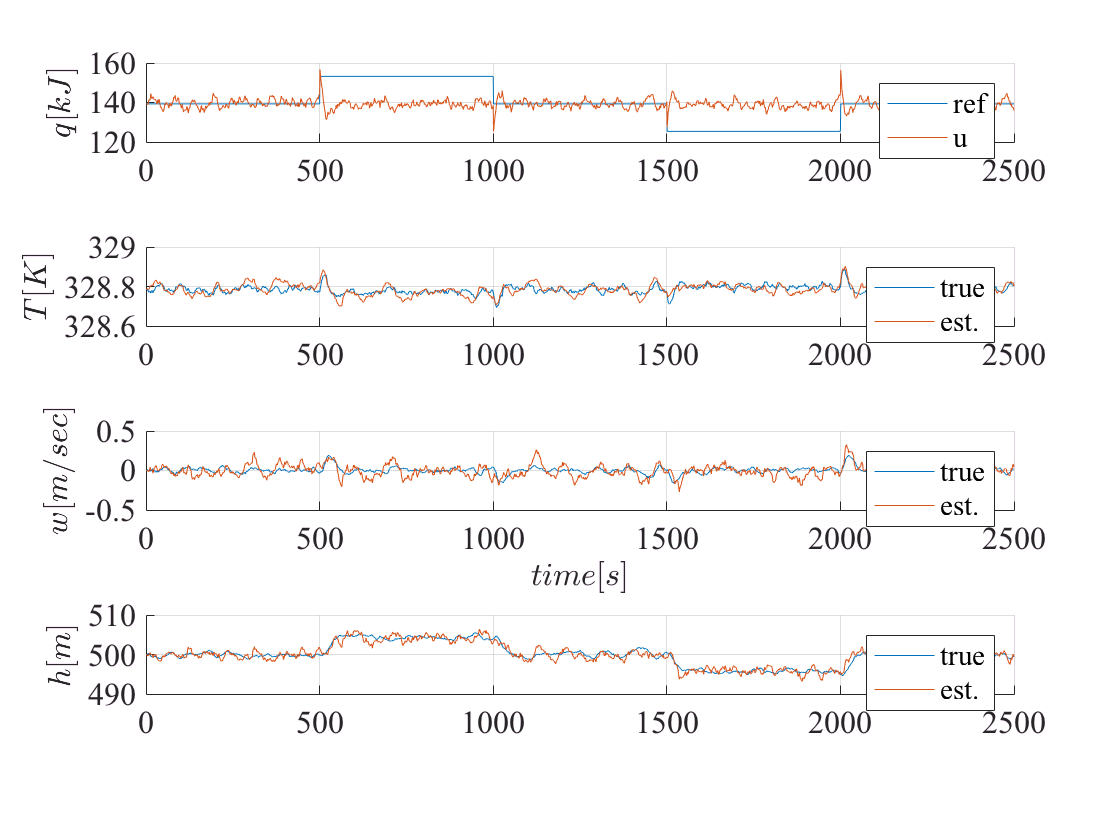

% the feedback gain found in Problem 1
K = Kp1


% Run stochastic simulation
stoc = 1;      % 0: Deterministic, 1: Stochastic
sim('M17_Q2',2500, [],[t' delta_u']);
figure, h0 = subplot(4,1,1); set(h0,'FontName','times','FontSize',16);
hold on, grid on;
plot(q.time,[us+r.signals.values,q.signals.values]);

K =   156.9725   62.6696    3.7273

ylabel('$q [kJ]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('ref', 'u')

h1 = subplot(4,1,2); set(h1,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,[sim_x.signals.values(:,1),sim_xhat.signals.values(:,1)]);
ylabel('$T [K]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('true', 'est.')

h2 = subplot(4,1,3); set(h2,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,[sim_x.signals.values(:,2),sim_xhat.signals.values(:,2)]);
ylabel('$w [m/sec]$','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('$time [s]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('true', 'est.')

h3 = subplot(4,1,4); set(h3,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,[sim_x.signals.values(:,3),sim_xhat.signals.values(:,3)]);
ylabel('$h [m]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('true', 'est.')

**Problem 3**  Now use the state estimates to close the loop using the LQR regulator designed in **Problem 1**. It may be necessary to adjust the state weights to increase the feedback level to achieve stability. Does the Kalman filter improve the quality of the regulator (reduce the state error)?

**Solution:**

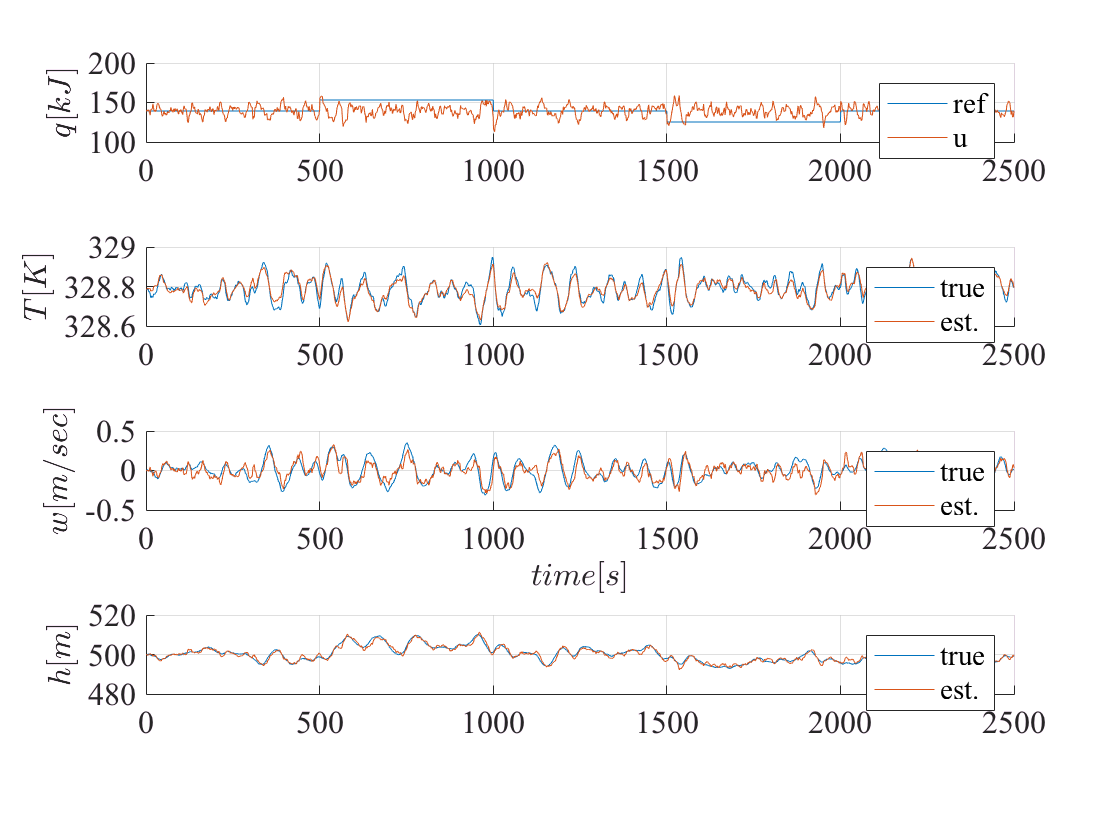

% the feedback gain found in Problem 1
K = Kp1

% Run stochastic simulation
stoc = 1;      % 0: Deterministic, 1: Stochastic
sim('M17_Q3',2500, [],[t' delta_u']);
figure, h0 = subplot(4,1,1); set(h0,'FontName','times','FontSize',16);

hold on, grid on;
plot(q.time,[us+r.signals.values,q.signals.values]);
ylabel('$q [kJ]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('ref', 'u')

h1 = subplot(4,1,2); set(h1,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,[sim_x.signals.values(:,1),sim_xhat.signals.values(:,1)]);
ylabel('$T [K]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('true', 'est.')

h2 = subplot(4,1,3); set(h2,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,[sim_x.signals.values(:,2),sim_xhat.signals.values(:,2)]);
ylabel('$w [m/sec]$','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('$time [s]$','FontName','times','FontSize',16,'Interpreter','latex');

us400 = 138.5090

legend('true', 'est.')

xs400 =   329.1527
         0
  400.0000


h3 = subplot(4,1,4); set(h3,'FontName','times','FontSize',16);
hold on, grid on;

K =   156.9725   62.6696    3.7273

plot(sim_x.time,[sim_x.signals.values(:,3),sim_xhat.signals.values(:,3)]);
ylabel('$h [m]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('true', 'est.')

**Problem 4**  The LQR has been designed to work at an altitude of 500 m. It is of interest to find out how robust it is with respect to changes in its operating point. Change the reference for the system so that the system operates at 400 m without changing the feedback gains. Is the system still stable? What does this say about the robustness of LQR regulators. For this simulations use the LQR regulator alone without the Kalman filter.

**Solution:**

***1 . Close loop with LQR***

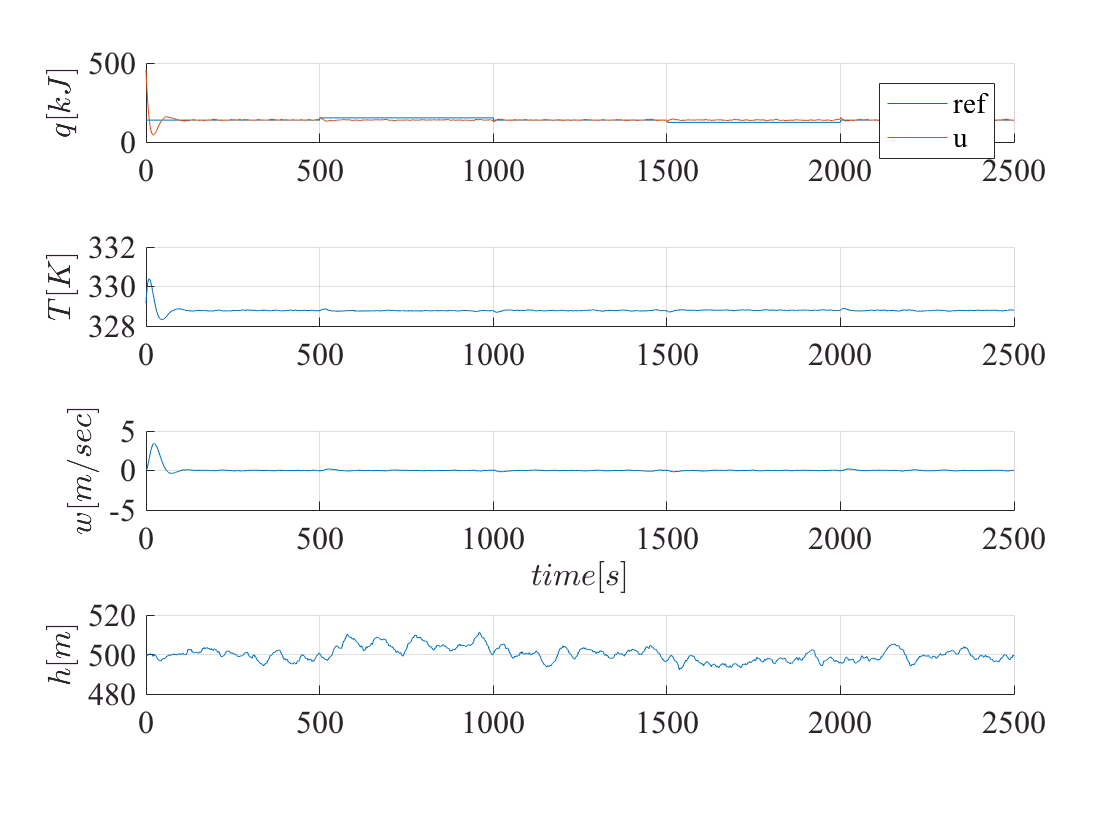

% Compute new values for system model
hs400 = 400;   %m,   linearizing point
ws400 = 0;     %m/s, linearizing point

%% Solution From Module 16:
Tah=Ta0-f*hs400;
rhoah=rhoa0-p*hs400;
rho=-(M*g)/(V*g)+rhoah;  
Ts400=rhoah*Tah/rho;
q0=(1/tau1*(Ts400-Tah))/c;
us400=q0
xs400 = [Ts400 ws400 hs400]'

% the feedback gain found in Problem 1
K = Kp1

% Run stochastic simulation
stoc = 1;      % 0: Deterministic, 1: Stochastic
delta_u= (0.1*us).*[zeros(1,500) ones(1,500) zeros(1,500) -1*ones(1,500) zeros(1,500)];
t=1:2500;
sim('M17_Q4',2500, [],[t' delta_u']);
figure, h0 = subplot(4,1,1); set(h0,'FontName','times','FontSize',16);
hold on, grid on;
plot(q.time,[us400+r.signals.values,q.signals.values]);

ylabel('$q [kJ]$','FontName','times','FontSize',16,'Interpreter','latex');
legend('ref', 'u')

h1 = subplot(4,1,2); set(h1,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_x.signals.values(:,1));
ylabel('$T [K]$','FontName','times','FontSize',16,'Interpreter','latex');

h2 = subplot(4,1,3); set(h2,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_x.signals.values(:,2));
ylabel('$w [m/sec]$','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('$time [s]$','FontName','times','FontSize',16,'Interpreter','latex');

h3 = subplot(4,1,4); set(h3,'FontName','times','FontSize',16);
hold on, grid on;
plot(sim_x.time,sim_xhat.signals.values(:,3));
ylabel('$h [m]$','FontName','times','FontSize',16,'Interpreter','latex');